依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

长时间相同光水任务的热图

DataSet=TransferLearning.FullCalcium;

排序热图2

LAKeep=UniExp.NtatsCellStrip(DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'OriginalKeepTraining'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));

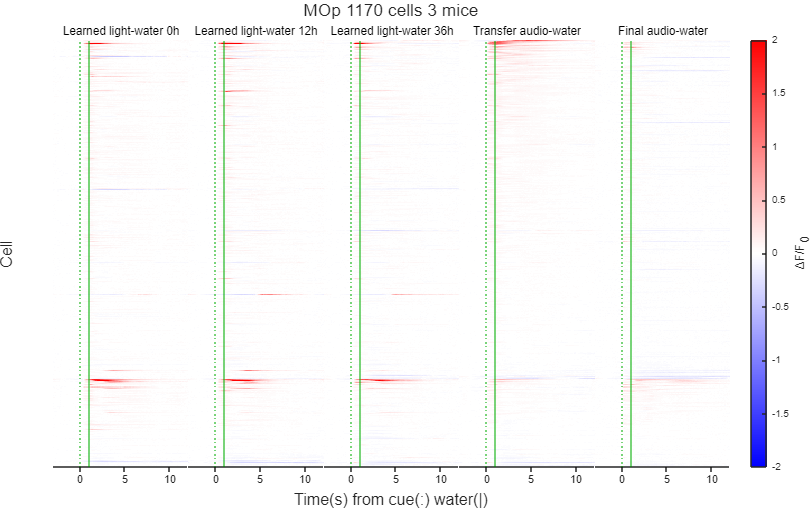

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Data=UniExp.HeatmapSort(LAKeep,["Transfer_audio_water","Final_audio_water"],'descend').NTATS{:,:,["Learned_light_water_0h","Learned_light_water_12h","Learned_light_water_36h","Transfer_audio_water","Final_audio_water"]};
NumMice=numel(unique(DataSet.Cells.Mouse(ismember(DataSet.Cells.CellUID,LAKeep.CellUID))));
Layout=TransferLearning.BasicHeatmap(Data,["Learned light-water 0h","Learned light-water 12h","Learned light-water 36h","Transfer audio-water","Final audio-water"],Colors,false,CLim=[-2,2]);
MATLAB.Graphics.FigureAspectRatio(8,5,2);
title(Layout,sprintf('MOp %u cells %u mice',height(LAKeep),NumMice));
print(TransferLearning.ProjectPath('OriginalKeepTraining.svg'),'-dsvg');

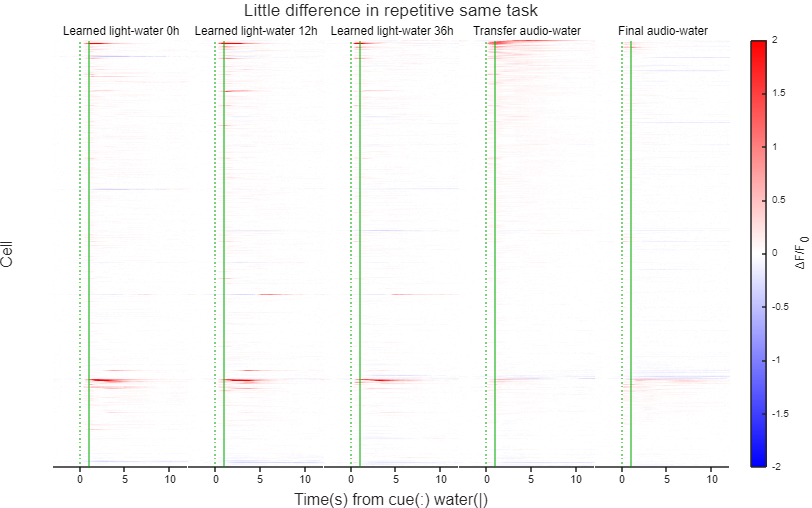

title(Layout,'Little difference in repetitive same task');
print(TransferLearning.ProjectPath('OriginalKeepTraining.PPT.svg'),'-dsvg');